# 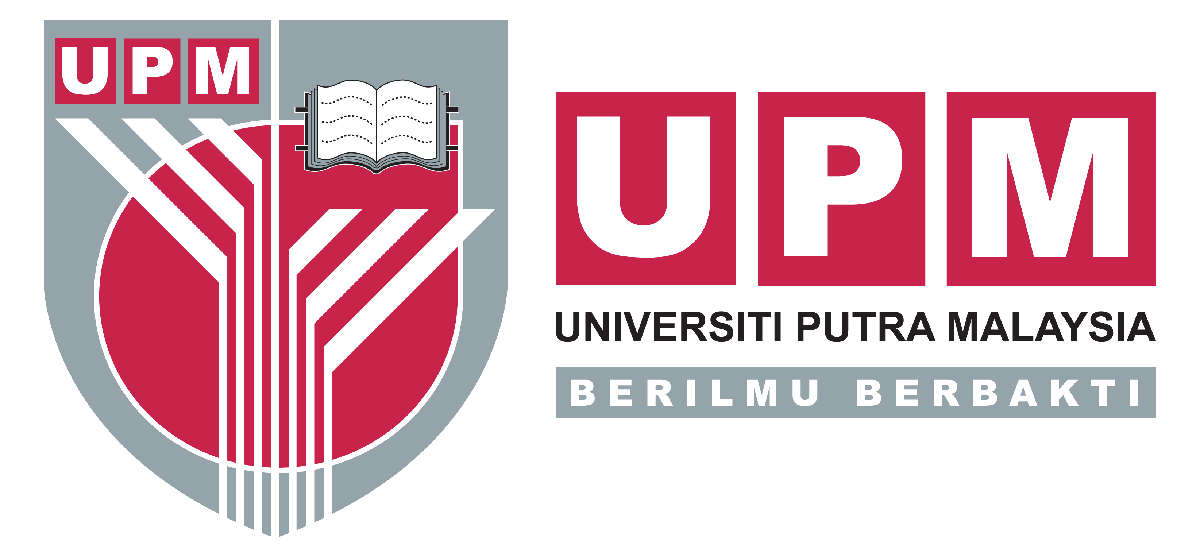

# **Gravity and Clustering**

**Mini Project | Computational Physics (PHY4602) | Semester 1 2023/2024**

**Chapter: Astrophysics and Cosmology in (pg. 216-217)**

**Group Members**

- Lim Soo Sim (205365)

- Tham Jia Yi (205623)

- Elia Natasha binti M.Azahari (209040)

- Ang Kai Liang (209031)

### **Introduction**

Gravity is the universal fundamental force exerted by a planet that makes other bodies attract toward its centre. In real life, it is crucial to keep us on the ground. In fact, the object with a greater mass has a larger gravity to pull the weaker or smaller object toward itself. Newton’s law of universal gravitation states that the attractive force between any two objects is directly proportional to the product of their masses and inversely proportional to the square of separation apart.


$$F_g =-\frac{Gm_1 m_2 }{r^2 }$$


where G is universal gravitational constant, $m_1$ and $m_2$ is the mass of the objects and r is the distance between the two objects.  

Therefore, gravity plays a dominant role that influences the clustering in space. It causes an attraction between planets orbiting around the Sun, then the stars moving around the centre of the galaxy and galaxies to cluster together. 

Figure 1: An animation of gravity at work. Source: [NASA Science](https://spaceplace.nasa.gov/what-is-gravity/en/)

### **Formation of Galaxy Clusters and Superclusters**

Galaxy clusters are the universe’s biggest objects, held together by their respective gravity. They contain hundreds or thousands of galaxies, as well as a significant amount of hot plasma and invisible dark matter. Galaxy clusters contain the largest galaxies in the known universe and give information about the cosmos's structure at the greatest scales.

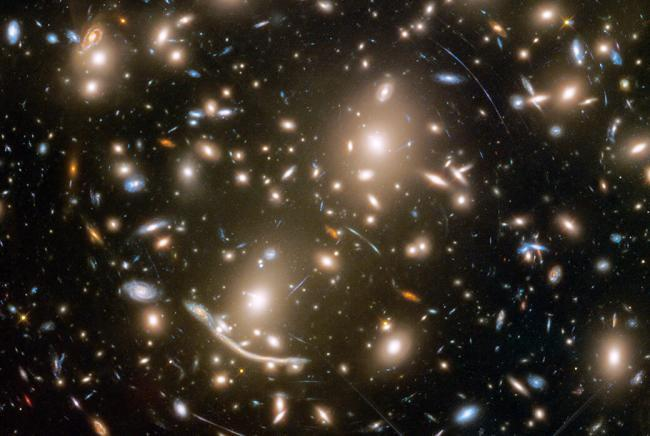

Figure 2: Galaxy Cluster Abell 370. Source: [CFA Harvard](https://www.cfa.harvard.edu/research/topic/galaxy-clusters)

Investigations have shown increasing evidence for galaxies' concentrations, filaments, clusters, and superclusters when the universe was less than 3 billion years old. This suggests that massive concentrations of galaxies formed when the universe was less than a fourth of its current age. The picture below depicts the centre of one of the most distant galaxy clusters ever identified, SpARCS 1049+56, as it appeared approximately ten billion years ago. The image's surprise was the "train wreck" of disordered galaxy forms and blue tidal tails: it appears that multiple galaxies in the core are merging, which is most likely the origin of the cluster's huge burst of star creation and brilliant infrared emission.

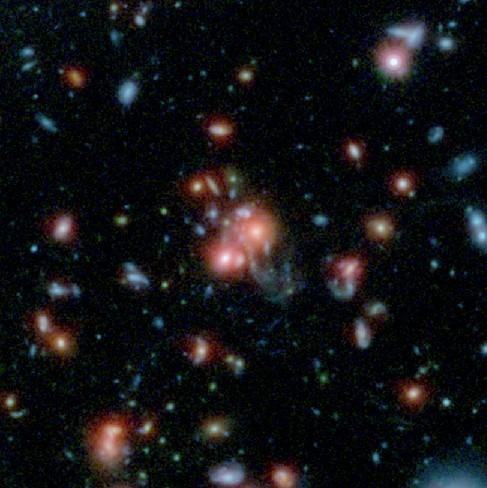

Figure 3: Merging Galaxies in a Distant Cluster. Source: [Lumen Learning](https://courses.lumenlearning.com/suny-astronomy/chapter/the-formation-and-evolution-of-galaxies-and-structure-in-the-universe/#:~:text=Clusters%20of%20galaxies%20then%20formed,clusters%20and%2C%20eventually%2C%20superclusters)

Individual galaxies clustered and were brought together by their mutual gravitational attraction, forming clusters. First, a few galaxies joined together to create groupings, similar to our own **Local Group**. The groupings then started joining to create clusters, and finally superclusters. The model predicts that clusters and superclusters are still in the process of forming, and measurements show that clusters are continually accumulating their flocks of galaxies and collecting additional gas as it flows in via filaments.

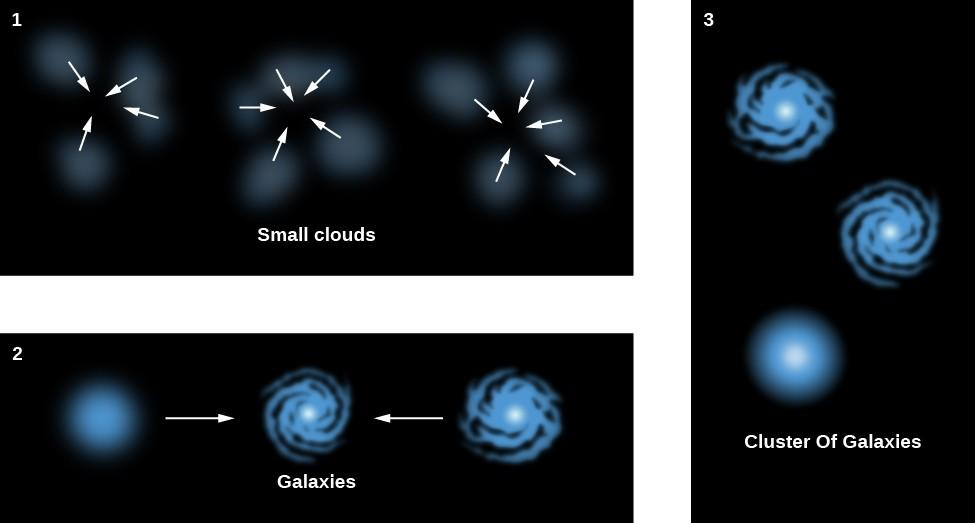

Figure 4: Formation of Cluster of Galaxies. Source: [Lumen Learning](https://courses.lumenlearning.com/suny-astronomy/chapter/the-formation-and-evolution-of-galaxies-and-structure-in-the-universe/#:~:text=Clusters%20of%20galaxies%20then%20formed,clusters%20and%2C%20eventually%2C%20superclusters)

Superclusters are massive cosmic filaments, sheets, or walls made up of many galaxy clusters and groups joined by enormous cosmic gaps. Supercluster creation is the result of a complicated interaction between gravity and the universe's large-scale matter distribution. Galaxy clusters and superclusters continue to expand when smaller structures merge to produce larger ones. Here, the code at the next section illustrates this fact by simulating a two dimensional system of particles self-interacting under gravity. This enables us to visualise this whole concept with the utilisation of MATLAB simulation.

### **Simulation of Particles Evolving in a 2D Gravity Field**

We know that gravity is always attractive as the negative sign in the equation given by Newton's universal gravitational law. Thus, it will always win in any given situation which results in clustering. To demonstrate the gravitational clustering, we assume that the particles begin at rest at random positions in a box with the absence of temperature. When the particles come into contact with one another, they form clusters. They will stop moving and become inert. 

After running the simulation, users are prompted to insert the number of particles in the command window.

% Program to look at clumping of a system under gravity, zero temperature
% 
clear all;  
help Grav_Clump      % Clear the memory and print header

  
  Program to look at clumping of a system under gravity, zero temperature



%
iloop = 0;
%

    %
    clear 'xx' 'yy' 'iclump' 'x' 'y' 'vx' 'vy' 'vxx' 'vyy'
    %
    % put N particles randomly in a 2-d box and let them
    % evolve under mutual gravitational attraction
    %
    fprintf('N Particles in 2-d Evolving Under Mutual Gravitational Attraction \n')

N Particles in 2-d Evolving Under Mutual Gravitational Attraction 


    %
    N = input('Enter a Number of Particles to Track: ');
    %
    % initial conditions, random locations, start with all at rest
    %
        for i = 1:N
            x(i) = rand;
            y(i) = rand;
            vx(i) = 0;
            vy(i) = 0;
            xx(i,1) = x(i);  % initial locations for a movie
            yy(i,1) = y(i);
            vxx(i,1) = 0;
            vyy(i,1) = 0;
            iclump(i) = 0;   % key for a pair of clumped particles
        end
        %
        % initial clumping
        %

The separation between two particles in 2D is given as:


$$d=\sqrt{{\left(x_2 -x_1 \right)}^2 +{\left(y_2 -y_1 \right)}^2 }$$


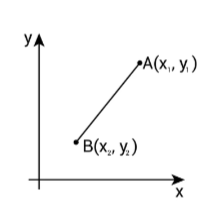

Figure 5: Shortest Distance Between Two Points in a Two-Dimensional Space. Source: [HowStuffWorks](https://science.howstuffworks.com/math-concepts/distance-formula.htm)

While the root mean square (r.m.s) separation of particles is $\sqrt{\frac{d_0^2 +d_1^2 +d_2^2 +\ldotp \ldotp \ldotp +d_N^2 }{n}}$, where the n is the number of particle’s pair, $n=N^2$. Note that the pair includes the particle with itself and the repeated pair. For instance, there are three particles, P1, P2 and P3 in an empty box, then n = 9.

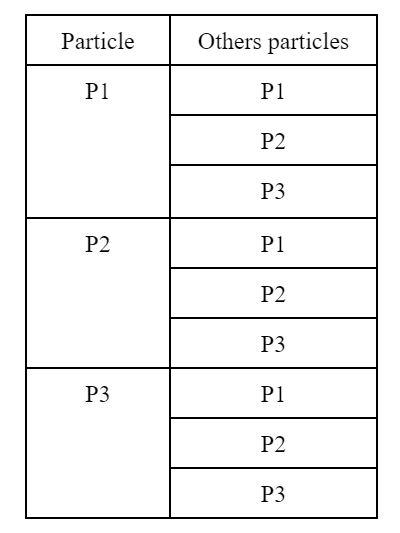

(P1, P1), (P1, P2), (P1, P3), (P2, P1), (P2, P2), (P2, P3), (P3, P1), (P3, P2), (P3, P3) = 9 pairs

Now, in order to calculate the initial root mean square (r.m.s.), we apply the distance formula (separation), the code is as below:

        dRij = 0;     % dRij = initial mean separation
        for i = 1:N
            for j = 1:N
                dRij = dRij + (xx(i,1)-xx(j,1)) .^2 + (yy(i,1)-yy(j,1)) .^2;
            end
        end
        dRij = sqrt(dRij ./ (N .^2));
        fprintf('Initial R.M.S Seperation %g  \n',dRij);

Initial R.M.S Seperation 0.644447  


        %
        dt = 0.02;    % time steps
        if N == 3
            dt = 0.012;
        end
        if N > 3
            dt = 0.004;
        end

We compute both gravitational force, $F_x$ and $F_y$ exerted by a particle on other particles. 

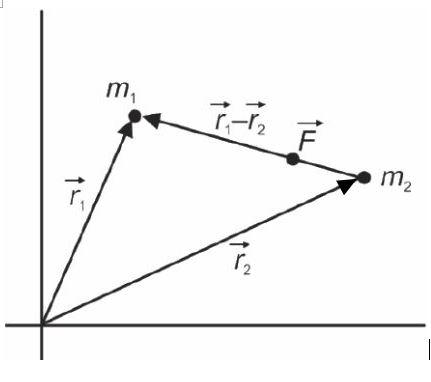

Figure 6: Vector form of Gravitational law. Source: [BYJU'S](https://byjus.com/question-answer/gravitational-law-in-vector-form-gravitational-potential-energy/)

The vector form of gravitational force in x-direction is given as $\vec{F_x } =\frac{Gm_1 m_2 }{r^3 }\vec{r_x }$ whereas the vector form of gravitational force in y-direction is given as $\vec{F_y } =\frac{Gm_1 m_2 }{r^3 }\vec{r_y }$. Assume that the product of  $G$ with $m_1$and $m_2$ is negligible in the following code. We set the particles to clump together and become inert when the particle pair satisfies the condition either r is small or force is larger.

Besides, Euler’s method is used in calculating the new velocity, $v$ and position, $x$ of the particles at every time step,$\Delta t$. Thus, the new $v=v+F\Delta t$ whereas the new $x=x+v\Delta t$. 

        kmax = 100;   % max number of time steps
        %
        for k = 2:kmax   % time steps
            l = k-1;
            for i = 1:N  % loop over all particles
            %
            % find force on i from all other particles j
            %
                fx(i) = 0;
                fy(i) = 0;
                for j = 1:N
                    if i ~= j && iclump(j) == 0 ;  % make clumped inert
                        r = sqrt((xx(i,l) - xx(j,l)) .^2 + (yy(i,l) - yy(j,l)) .^2)+ 0.01;
                        fx(i) = fx(i) + (xx(j,l) - xx(i,l)) ./(r .^3);
                        fy(i) = fy(i) + (yy(j,l) - yy(i,l)) ./(r .^3);
                        %
                        % clumping, trap on small r or large force
                        %
                        if r < 0.01 | abs(fx(i)) > 200 | abs(fy(i)) > 200
                            iclump(i) = 1;   % this i*j pair is now inert
                            iclump(j) = 1;
                            vxx(j,k) = 0;
                            vyy(j,k) = 0;
                            xx(j,k) = xx(i,l)+ 0.01;
                            yy(j,k) = yy(i,l)+ 0.01;
                        end
                    end
                end
                %
                vxx(i,k) = vxx(i,l) + fx(i) .*dt;   % assume particle mass negligible
                vyy(i,k) = vyy(i,l) + fy(i) .*dt;
                xx(i,k) = xx(i,l) + vxx(i,l) .*dt;
                yy(i,k) = yy(i,l) + vyy(i,l) .*dt;
                if iclump(i) > 0    % iclump = key for a pair of clumped particles
                    vxx(i,k) = 0;
                    vyy(i,k) = 0;
                    xx(i,k) = xx(i,l);
                    yy(i,k) = yy(i,l);
                end
                %
                % keep the particles in the box
                %
                if xx(i,k) < 0 | xx(i,k) > 1
                    vxx(i,k) = -vxx(i,k);
                end
                if yy(i,k) < 0 | yy(i,k) > 1
                    vyy(i,k) = -vyy(i,k);
                end
                %
            end
        end
        %
        % final clumping
        %
        dRij = 0;
        for i = 1:N
            for j = 1:N
                dRij = dRij + (xx(i,kmax)-xx(j,kmax)) .^2 + (yy(i,kmax)-yy(j,kmax)) .^2;
            end
        end


After finding the final r.m.s. separation value, the movie of evolution of the system is visualised. With several trials of different numbers of particles, we can observe that as the number of particles increased, the easier the particles clumped together.

        dRij = sqrt(dRij ./(N .^2));
        fprintf('Final R.M.S Seperation %g  \n',dRij);

Final R.M.S Seperation 0.490594  


        %
        fprintf(' Movie of Evolution of the System \n');

 Movie of Evolution of the System 


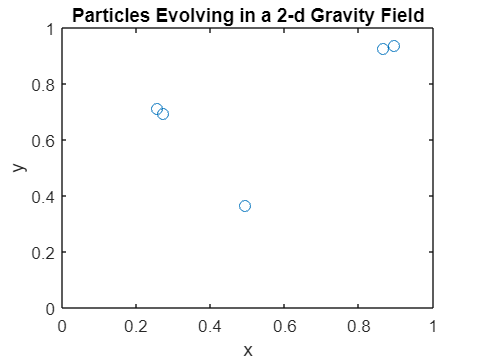

        %
        iloop = iloop + 1 ;
        figure(iloop)
      
        for k = 1:kmax
            plot(xx(:,k),yy(:,k),'o')
            xlabel('x')
            ylabel('y')
            title('Particles Evolving in a 2-d Gravity Field')
            axis([0 1 0 1])
            pause(0.1)
        end

        %

### **Conclusion**

Less dense systems can stay unclumped for extended periods of time. This reflects the fact that increasing density causes more particles to feel larger gravitational pulls due to the force's inverse square nature. Thus, we can conclude the concept in two crucial ways:

- As the number of particles, N increases, the initial and final r.m.s. are almost identical.

- As the number of particles, N increases, the density increases.

Hence the higher density means the particles are not easy to move around. This fact may be approximated by running the model with varying amounts of total particles. Cluster time is around 15 billion years for a density of $2\times {10}^{-26} \;\textrm{kg}/m^3$, which is close to the Universe's average density.